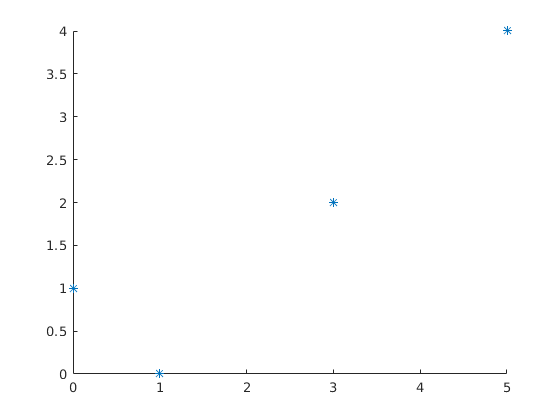

clf
hold on
x_data = [0; 1; 3; 5];
y_data = [1; 0; 2; 4];
plot(x_data, y_data, '*')

A_data = [x_data.^2 x_data ones(size(x_data))];
p = A_data\y_data

p =     0.1910
   -0.2663
    0.6784


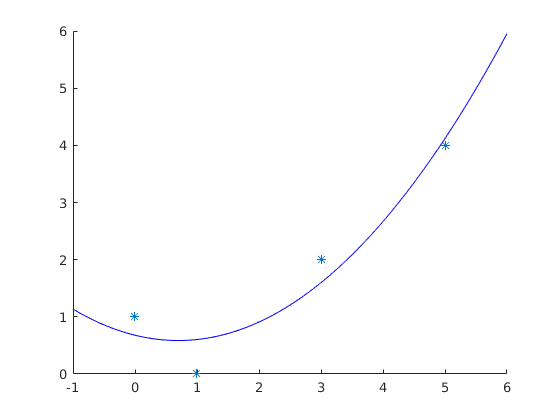

x = linspace(-1, 6, 1000)';
A = [x.^2 x ones(size(x))];
y = A * p;
plot(x, y, 'b')

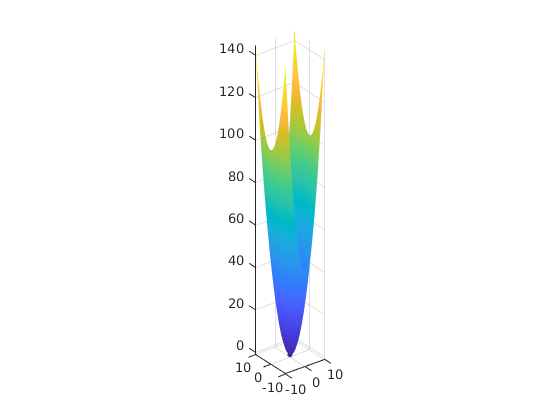

hold off

clf

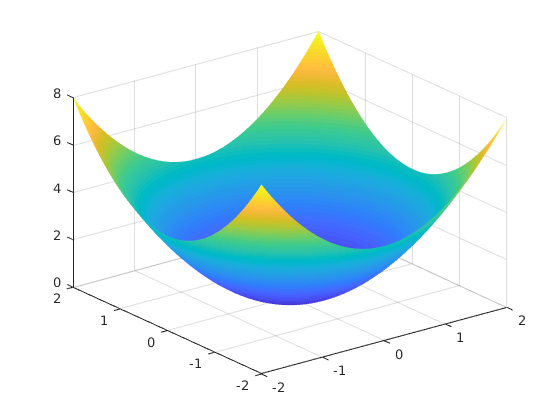

[x, y] = meshgrid(linspace(-2, 2, 100), linspace(-2, 2, 100));
z = x.^2 + y.^2;
surf(x, y, z);
shading interp

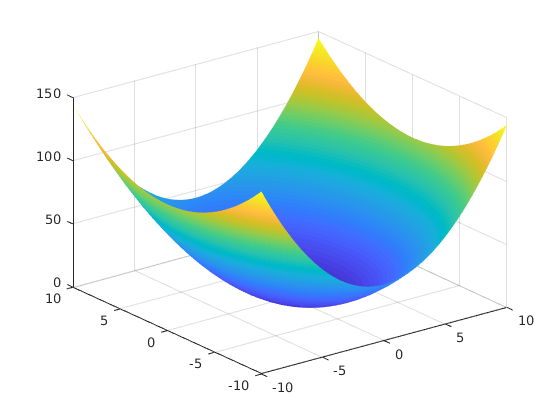

[x, y] = meshgrid(linspace(-10, 10, 100), linspace(-10, 10, 100));
a = 1;
b = 1.5;
z = x.^2/a^2 + y.^2/b^2;
surf(x, y, z);
shading interp

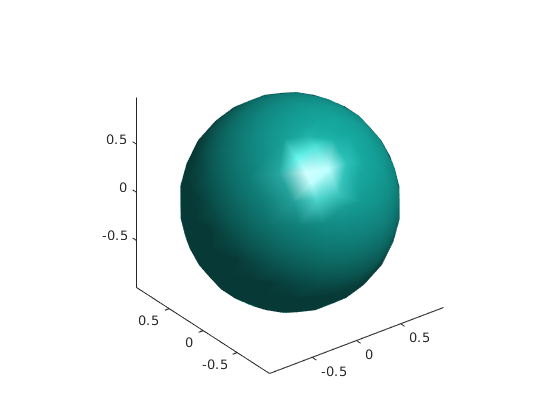

hold off

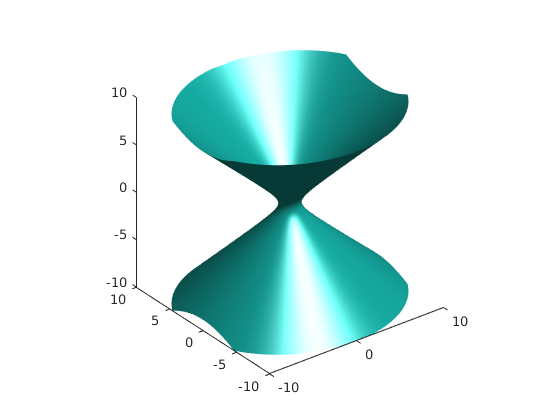

clf
a = 1.12;
b = 1;
c = 1;
[x,y,z] = meshgrid(linspace(-10,10,100),linspace(-10,10,100),linspace(-10,10,100));
f = x.^2/a^2 + y.^2/b^2 - z.^2/c^2 - 1;
isosurface(x, y, z, f, 0)
axis equal

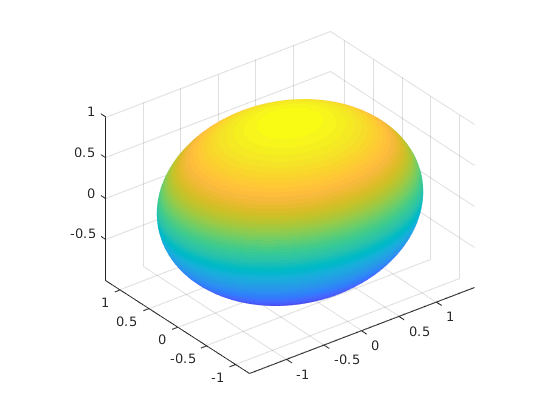

clf
a = 1.5;
b = 1.25;
c = 1;
[u, v] = meshgrid(linspace(0,2*pi,200),linspace(0,2*pi,200));
x = a*cos(u).*sin(v);
y = b*sin(u).*sin(v);
z = c*cos(v);
surf(x, y, z)
shading interp
axis equal

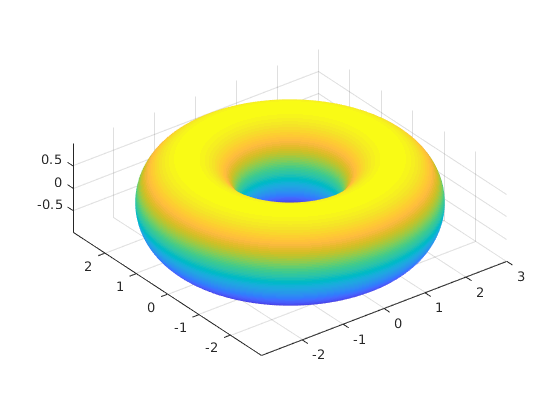

clf
a = 2;
r = 1;
[u, v] = meshgrid(linspace(0,2*pi,200),linspace(0,2*pi,200));
x = (a+r*cos(u)).*cos(v);
y = (a+r*cos(u)).*sin(v);
z = r*sin(u);
surf(x, y, z)
shading interp
axis equal